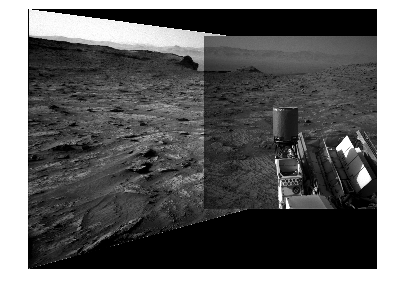

imgM = imread("sol1.JPG"); % Moving Image
imgF = imread("sol2.JPG"); % Fixed Image

imgM = cat(3, imgM, imgM, imgM);
imgF = cat(3, imgF, imgF, imgF);

img_pan = stitch_RGB_images(imgM, imgF);
imshow(img_pan);

function [Panorama] = stitch_RGB_images(moving_img, fixed_img)
imgM = moving_img;
imgF = fixed_img;

grayM = im2gray(imgM);
grayF = im2gray(imgF);

% Match Registration Function
movingreg = registerImages(grayM, grayF);

% Panorama image delimitation from the moving image transformation
% and fixed image. The idea is too get the limits necessary to hold
% both images in the stiching format  to create a panorama image
% that will serve as a canvas.

movingT = movingreg.Transformation;
fixedT = rigidtform2d();

[nrows, ncols, ~] = size(imgM);
[xlimmov, ylimmov] = outputLimits(movingT, [1 ncols], [1 nrows]);
[xlimfix, ylimfix] = outputLimits(fixedT, [1 ncols], [1 nrows]);

xMin = min([xlimmov, xlimfix]);
xMax = max([xlimmov, xlimfix]);
yMin = min([ylimmov, ylimfix]);
yMax = max([ylimmov, ylimfix]);

w = round(xMax - xMin);
h = round(yMax - yMin);

panorama = zeros([h, w, 3], "uint8");
panoramaView = imref2d([h w], [xMin xMax], [yMin yMax]);

movingWarp = imwarp(imgM, movingT, "OutputView", panoramaView);
fixedWarp = imwarp(imgF, fixedT, "OutputView", panoramaView);

mask = ones(nrows, ncols, "logical");
movingMask = imwarp(mask, movingT, "OutputView", panoramaView);
fixedMask = imwarp(mask, fixedT, "OutputView", panoramaView);

blender = vision.AlphaBlender("Operation","Binary Mask", "MaskSource","Input port");
panorama = blender(panorama, movingWarp, movingMask);
panorama = blender(panorama, fixedWarp, fixedMask);
Panorama = panorama;

function [MOVINGREG] = registerImages(MOVING,FIXED)
%registerImages  Register grayscale images using auto-generated code from Registration Estimator app.
%  [MOVINGREG] = registerImages(MOVING,FIXED) Register grayscale images
%  MOVING and FIXED using auto-generated code from the Registration
%  Estimator app. The values for all registration parameters were set
%  interactively in the app and result in the registered image stored in the
%  structure array MOVINGREG.

% Auto-generated by registrationEstimator app on 10-Feb-2025
%-----------------------------------------------------------


% Feature-based techniques require license to Computer Vision Toolbox
checkLicense()

% Default spatial referencing objects
fixedRefObj = imref2d(size(FIXED));
movingRefObj = imref2d(size(MOVING));

% Detect SURF features
fixedPoints = detectSURFFeatures(FIXED,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);
movingPoints = detectSURFFeatures(MOVING,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);

% Extract features
[fixedFeatures,fixedValidPoints] = extractFeatures(FIXED,fixedPoints,'Upright',false);
[movingFeatures,movingValidPoints] = extractFeatures(MOVING,movingPoints,'Upright',false);

% Match features
indexPairs = matchFeatures(fixedFeatures,movingFeatures,'MatchThreshold',50.000000,'MaxRatio',0.500000);
fixedMatchedPoints = fixedValidPoints(indexPairs(:,1));
movingMatchedPoints = movingValidPoints(indexPairs(:,2));
MOVINGREG.FixedMatchedFeatures = fixedMatchedPoints;
MOVINGREG.MovingMatchedFeatures = movingMatchedPoints;

% Apply transformation - Results may not be identical between runs because of the randomized nature of the algorithm
tform = estimateGeometricTransform2D(movingMatchedPoints,fixedMatchedPoints,'projective');
MOVINGREG.Transformation = tform;
MOVINGREG.RegisteredImage = imwarp(MOVING, movingRefObj, tform, 'OutputView', fixedRefObj, 'SmoothEdges', true);

% Store spatial referencing object
MOVINGREG.SpatialRefObj = fixedRefObj;

end

function checkLicense()

% Check for license to Computer Vision Toolbox
CVTStatus = license('test','Video_and_Image_Blockset');
if ~CVTStatus
    error(message('images:imageRegistration:CVTRequired'));
end

end

end